依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

左半边B，光水的初始和迁移学习曲线；右半边C，光水和声水的学会会话数条形图

BehaviorDataSet=TransferLearning.BasicTransferBehaviorDataSet;

SessionTableAL=BehaviorDataSet.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="LightWater");
SessionTableAL.Group(:)="Transfer";
SessionTableLL=BehaviorDataSet.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="LightWater");
SessionTableLL.Group(:)="Original";
SessionTableAA=BehaviorDataSet.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="AudioWater");
SessionTableAA.Group(:)="Original";
SessionTableLA=BehaviorDataSet.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="AudioWater");
SessionTableLA.Group(:)="Transfer";
SummaryL=UniExp.LearningSummarize([SessionTableAL;SessionTableLL],0.95);SummaryA=UniExp.LearningSummarize([SessionTableAA;SessionTableLA],0.95);
Colors=GlobalOptimization.ColorAllocate(2,[1,1,1;1,1,1]);
CompareGroup=table(["Original","Transfer"],'VariableNames',"GroupPair");

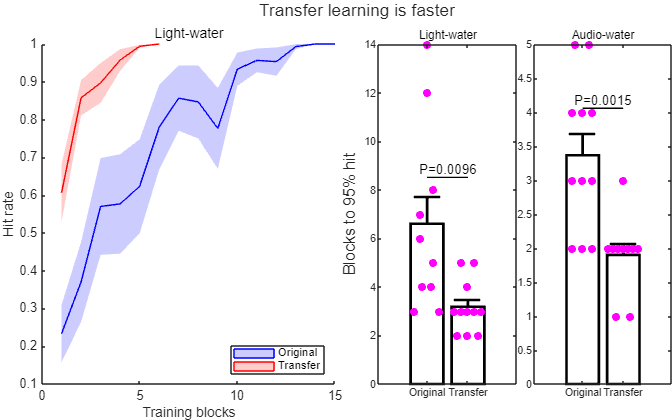

figure;
Layout1=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryL.MeanCurve,SummaryL.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,SummaryL.Properties.RowNames,Location='southeast');title('Light-water');
xlabel('Training blocks');
ylabel('Hit rate');
Layout2=tiledlayout(Layout1,1,2,TileSpacing='tight',Padding='tight');
Layout2.Layout.Tile=2;
nexttile(Layout2);
UniExp.BarScatterCompare(struct(Original=SummaryL.LearnedDays{"Original"}.Day,Transfer=SummaryL.LearnedDays{"Transfer"}.Day),CompareGroup);
title('Light-water');
nexttile(Layout2);
UniExp.BarScatterCompare(struct(Original=SummaryA.LearnedDays{"Original"}.Day,Transfer=SummaryA.LearnedDays{"Transfer"}.Day),CompareGroup);
title('Audio-water');
ylabel(Layout2,'Blocks to 95% hit');
title(Layout1,'Transfer learning is faster');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('Fig1BC.svg'),'-dsvg');